% 1. Load the data
data = readtable('C:\Users\yizha\qkd\FSOC\AO_simulation_log.csv')

data = 440×5 table
    timestep    E_power_sum    D_power_sum    num_airy    r0_ref
    ________    ___________    ___________    ________    ______

        0        9.118e+07      9.118e+07        2         0.01 
       20       9.5264e+07     3.1099e+08        2         0.01 
       40       9.8154e+07     3.0961e+08        2         0.01 
       60       9.6921e+07     3.0801e+08        2         0.01 
       80       9.3965e+07     3.0576e+08        2         0.01 
      100        9.273e+07     3.0488e+08        2         0.01 
      120       9.5062e+07     3.0324e+08        2         0.01 
      140       9.9722e+07     3.0264e+08        2         0.01 
      160       1.0467e+08      3.033e+08        2         0.01 
      180       1.0606e+08     3.0331e+08        2         0.01 
      200       1.1076e+08    


% Revert the data to true energy in Joules
scale_factor = 3.9e9;
true_E = data.E_power_sum / scale_factor;
true_D = data.D_power_sum / scale_factor;

%% 2. Time-Interval Aggregation (Row-Based)
interval_size = 780; % ms
time_jump = 20;      % ms
rows_per_interval = interval_size / time_jump; % Exactly 39 rows per cycle

num_rows = height(data); 

% Group into chunks of 39 rows (1-39 -> Group 1, 40-78 -> Group 2, etc.)
group_indices = floor((0:num_rows-1) / rows_per_interval)' + 1; 

% Calculate the mean energy for each 39-row interval
mean_E = accumarray(group_indices, true_E, [], @mean);
mean_D = accumarray(group_indices, true_D, [], @mean);

% --- DYNAMIC r0 EXTRACTION ---
% Calculate the mean r0 for each 39-row interval to perfectly match the energy data
% (Assumes 'r0' is a column in your 'data' table)
mean_r0 = accumarray(group_indices, data.r0_ref, [], @mean);


%% 3. Calculate AO Gain and Select 3 Specific Intervals
% Calculate the AO Gain (in dB) for every time interval
ao_gain_dB_all = 10 * log10(mean_D ./ mean_E);

% Sort the gains to find our three target atmospheric states
[sorted_gains, sorted_indices] = sort(ao_gain_dB_all);

min_idx = sorted_indices(1);
mid_idx = sorted_indices(round(length(sorted_indices)/2));
max_idx = sorted_indices(end);

target_intervals = [min_idx, mid_idx, max_idx];
interval_labels = {'Lowest AO Gain', 'Mid AO Gain', 'Highest AO Gain'};

fprintf('\nSelected Intervals:\n');


Selected Intervals:


for i = 1:length(target_intervals)
    idx = target_intervals(i);
    
    % Dynamically pull the r0 for this specific interval
    current_r0 = mean_r0(idx);
    
    % Convert to cm for printing (assuming your raw data stores it in meters)
    if current_r0 < 1 
        current_r0_cm = current_r0 * 100;
    else
        current_r0_cm = current_r0;
    end
    
    fprintf('%s (Index %d): Gain = %6.2f dB | r0 = %4.1f cm\n', ...
        interval_labels{i}, idx, ao_gain_dB_all(idx), current_r0_cm);
end

Lowest AO Gain (Index 11): Gain =   1.69 dB | r0 =  2.0 cm
Mid AO Gain (Index 7): Gain =   3.25 dB | r0 =  1.6 cm
Highest AO Gain (Index 2): Gain =   6.59 dB | r0 =  1.1 cm


%% 4. Simulate Specific Intervals
schemes_to_run = {'OOK', 'BPSK', 'DPSK', 'QAM4'}; 
% We increase the bits per point since we are no longer aggregating 100+ intervals together
num_bits_per_sim = 1e5; 

% Clean X-Axis sweep for the Uncorrected Signal
snr_sweep_dB = -5:2:20; 

results = struct();

for s = 1:length(schemes_to_run)
    mod_scheme = schemes_to_run{s};
    fprintf('Simulating %s...\n', mod_scheme);
    
    for lvl = 1:3
        current_interval = target_intervals(lvl);
        current_gain = ao_gain_dB_all(current_interval);
        
        % Uncorrected SNR is the baseline. Corrected SNR is simply shifted by the Gain.
        snr_E_dB_array = snr_sweep_dB;
        snr_D_dB_array = snr_sweep_dB + current_gain;
        
        ber_E_sim = zeros(1, length(snr_sweep_dB));
        ber_D_sim = zeros(1, length(snr_sweep_dB));
        ber_E_theory = zeros(1, length(snr_sweep_dB));
        ber_D_theory = zeros(1, length(snr_sweep_dB));

        for i = 1:length(snr_sweep_dB)
            tx_bits_e = randi([0 1], num_bits_per_sim, 1);
            tx_bits_d = randi([0 1], num_bits_per_sim, 1);

            %% --- Modulation, Noise, and Demodulation ---
            switch mod_scheme
                case 'OOK'
                    rx_sig_e = awgn(tx_bits_e, snr_E_dB_array(i), 'measured'); 
                    rx_bits_e = rx_sig_e > 0.5;
                    rx_sig_d = awgn(tx_bits_d, snr_D_dB_array(i), 'measured'); 
                    rx_bits_d = rx_sig_d > 0.5;
                    
                case 'BPSK'
                    % Force symbols to be complex so AWGN splits noise between I and Q
                    tx_sym_e = complex(2*tx_bits_e - 1, 0);
                    tx_sym_d = complex(2*tx_bits_d - 1, 0);
                    
                    rx_sig_e = awgn(tx_sym_e, snr_E_dB_array(i), 'measured'); 
                    % We only evaluate the Real (In-phase) part for our decision
                    rx_bits_e = real(rx_sig_e) > 0; 
                    
                    rx_sig_d = awgn(tx_sym_d, snr_D_dB_array(i), 'measured'); 
                    rx_bits_d = real(rx_sig_d) > 0;
                    
                case 'DPSK'
                    tx_sym_e = dpskmod(tx_bits_e, 2);
                    tx_sym_d = dpskmod(tx_bits_d, 2);
                    rx_sig_e = awgn(tx_sym_e, snr_E_dB_array(i), 'measured'); 
                    rx_bits_e = dpskdemod(rx_sig_e, 2); 
                    rx_sig_d = awgn(tx_sym_d, snr_D_dB_array(i), 'measured'); 
                    rx_bits_d = dpskdemod(rx_sig_d, 2); 
                    
                case 'QAM4'
                    tx_sym_e = qammod(tx_bits_e, 4, 'InputType', 'bit', 'UnitAveragePower', true);
                    tx_sym_d = qammod(tx_bits_d, 4, 'InputType', 'bit', 'UnitAveragePower', true);
                    rx_sig_e = awgn(tx_sym_e, snr_E_dB_array(i), 'measured'); 
                    rx_bits_e = qamdemod(rx_sig_e, 4, 'OutputType', 'bit', 'UnitAveragePower', true); 
                    rx_sig_d = awgn(tx_sym_d, snr_D_dB_array(i), 'measured'); 
                    rx_bits_d = qamdemod(rx_sig_d, 4, 'OutputType', 'bit', 'UnitAveragePower', true); 
            end
            
            % Count Errors
            ber_E_sim(i) = sum(tx_bits_e ~= rx_bits_e) / num_bits_per_sim;
            ber_D_sim(i) = sum(tx_bits_d ~= rx_bits_d) / num_bits_per_sim;
        end
        
        %% --- Theoretical Average BER Calculation ---
        switch mod_scheme
            case 'OOK'
                ber_E_theory = 0.5 * erfc(0.5 * sqrt(10.^(snr_E_dB_array / 10)));
                ber_D_theory = 0.5 * erfc(0.5 * sqrt(10.^(snr_D_dB_array / 10)));
            case 'BPSK'
                ber_E_theory = 0.5 * erfc(sqrt(10.^(snr_E_dB_array / 10)));
                ber_D_theory = 0.5 * erfc(sqrt(10.^(snr_D_dB_array / 10)));
            case 'DPSK'
                ber_E_theory = 0.5 * exp(-10.^(snr_E_dB_array / 10));
                ber_D_theory = 0.5 * exp(-10.^(snr_D_dB_array / 10));
            case 'QAM4'
                ber_E_theory = 0.5 * erfc(sqrt(0.5 * 10.^(snr_E_dB_array / 10)));
                ber_D_theory = 0.5 * erfc(sqrt(0.5 * 10.^(snr_D_dB_array / 10)));
        end
        
        % Zero-Error Handling for Logarithmic Plotting
        is_zero_E = (ber_E_sim == 0);
        is_zero_D = (ber_D_sim == 0);
        ber_E_sim(is_zero_E) = ber_E_theory(is_zero_E);
        ber_D_sim(is_zero_D) = ber_D_theory(is_zero_D);
        
        % Save to Struct under Scheme AND Level
        level_name = sprintf('level_%d', lvl);
        results.(mod_scheme).(level_name).gain_dB = current_gain;
        results.(mod_scheme).(level_name).snr_E = snr_E_dB_array;
        results.(mod_scheme).(level_name).ber_E = ber_E_sim;
        results.(mod_scheme).(level_name).snr_D = snr_D_dB_array;
        results.(mod_scheme).(level_name).ber_D = ber_D_sim;
        results.(mod_scheme).(level_name).theory_E = ber_E_theory;
        results.(mod_scheme).(level_name).theory_D = ber_D_theory;
        results.(mod_scheme).(level_name).is_zero_E = is_zero_E;
        results.(mod_scheme).(level_name).is_zero_D = is_zero_D;
    end
end

Simulating OOK...
Simulating BPSK...
Simulating DPSK...
Simulating QAM4...


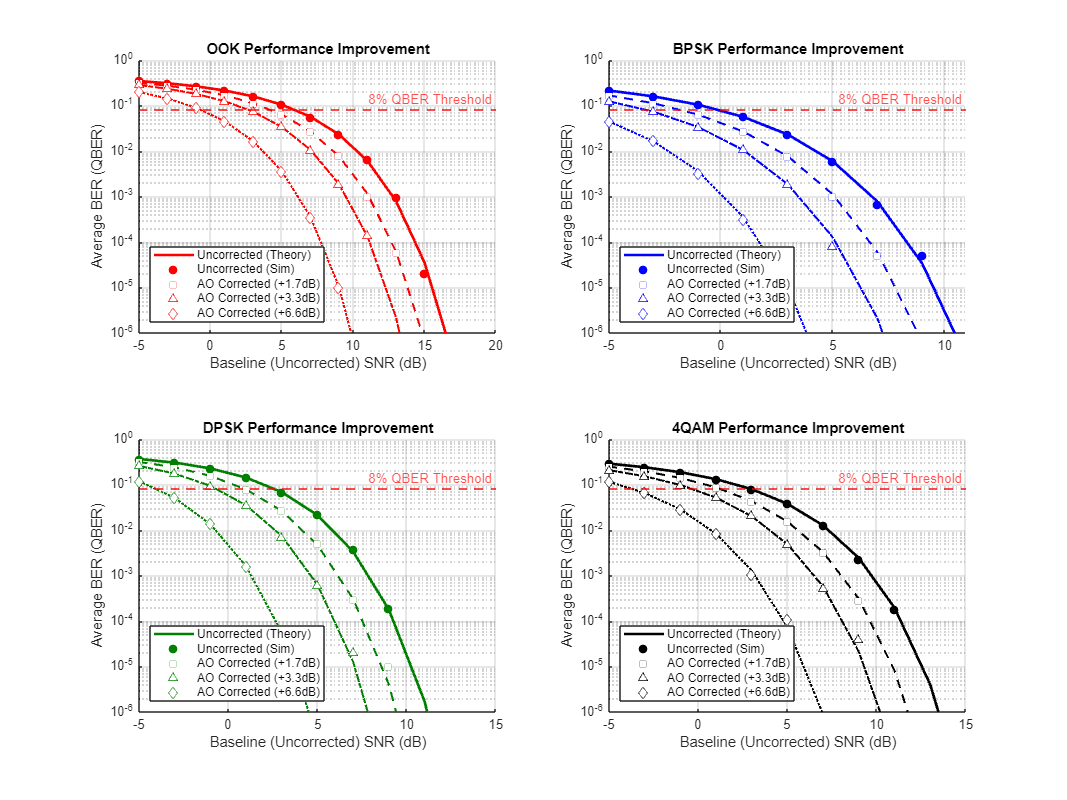

%% 5. Plot the Consolidated 2x2 Grid with QBER Threshold
figure('Position', [100, 100, 1200, 900]); 

% Using RGB triplets: Red, Blue, Dark Green, Black
color_map = containers.Map({'OOK', 'BPSK', 'DPSK', 'QAM4'}, ...
    {[1, 0, 0], [0, 0, 1], [0, 0.5, 0], [0, 0, 0]}); 

line_styles = {'-', '--', '-.', ':'};
markers = {'o', 's', '^', 'd'};

% QKD Security Threshold
qber_threshold = 0.08; 

for s = 1:length(schemes_to_run)
    mod_scheme = schemes_to_run{s};
    c = color_map(mod_scheme); % This is now an RGB array
    display_name = strrep(mod_scheme, 'QAM4', '4QAM');
    
    subplot(2, 2, s);
    hold on;
    
    % 1. Plot the UNCORRECTED baseline 
    data_base = results.(mod_scheme).level_1;
    mask_base = ~data_base.is_zero_E;
    
    % Plot uncorrected lines (Notice the updated 'Color' syntax)
    semilogy(data_base.snr_E, data_base.theory_E, '-', 'Color', c, 'LineWidth', 2, 'DisplayName', 'Uncorrected (Theory)');
    semilogy(data_base.snr_E(mask_base), data_base.ber_E(mask_base), 'o', 'Color', c, 'MarkerFaceColor', c, 'MarkerSize', 6, 'DisplayName', 'Uncorrected (Sim)');
    
    % 2. Plot the 3 CORRECTED levels against the BASELINE SNR
    for lvl = 1:3
        level_name = sprintf('level_%d', lvl);
        data = results.(mod_scheme).(level_name);
        mask_D = ~data.is_zero_D;
        
        gain_str = sprintf('AO Corrected (+%.1fdB)', data.gain_dB);
        
        semilogy(data.snr_E, data.theory_D, line_styles{lvl+1}, 'Color', c, 'LineWidth', 1.5, 'HandleVisibility', 'off'); 
        semilogy(data.snr_E(mask_D), data.ber_D(mask_D), markers{lvl+1}, 'Color', c, 'MarkerFaceColor', 'w', 'MarkerSize', 6, 'DisplayName', gain_str);
    end
    
    % 3. Add the QBER Security Threshold Line
    % We set HandleVisibility to 'off' so it doesn't clutter the legend
    yline(qber_threshold, '--r', '8% QBER Threshold', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'right', 'HandleVisibility', 'off');
    
    hold off;
    
    xlabel('Baseline (Uncorrected) SNR (dB)'); 
    ylabel('Average BER (QBER)');
    title(sprintf('%s Performance Improvement', display_name));
    grid on;
    set(gca, 'YScale', 'log', 'YLim', [1e-6 1]);
    
    legend('Location', 'southwest', 'FontSize', 9);
end

%% 6. Constellation Comparison Plots (Auto-Generate All AO Levels)

% Load the AO simulation log
ao_log_data = readtable('C:\Users\yizha\qkd\FSOC\AO_simulation_log.csv');

% Extract all unique r0 values
unique_r0s = unique(ao_log_data.r0_ref, 'stable');

% Calculate the minimum, median, and maximum r0 values
r0_min = min(unique_r0s);
r0_med = median(unique_r0s);
r0_max = max(unique_r0s);

% ---> SELECT WHICH r0 MATCHES YOUR CURRENT DATA HERE <---
r0_values = [inf,r0_max,r0_med,r0_min]

r0_values =        Inf    0.0200    0.0150    0.0100


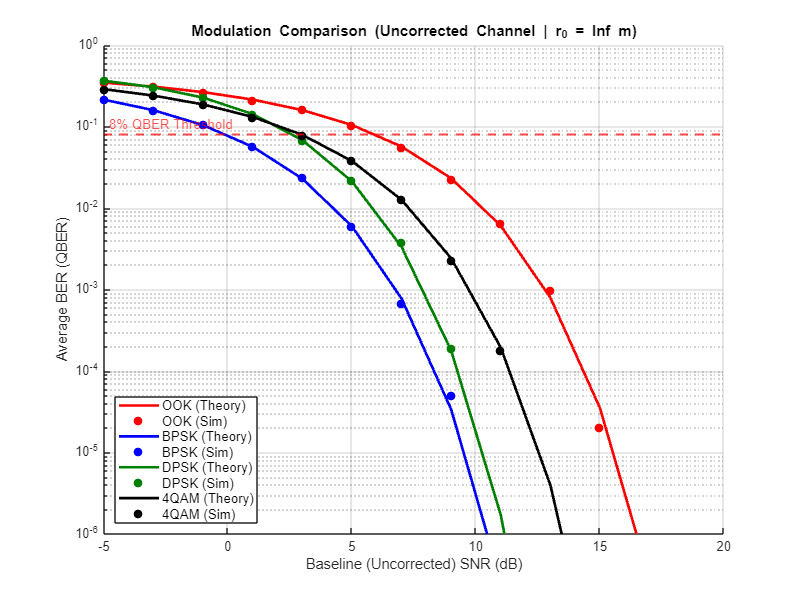

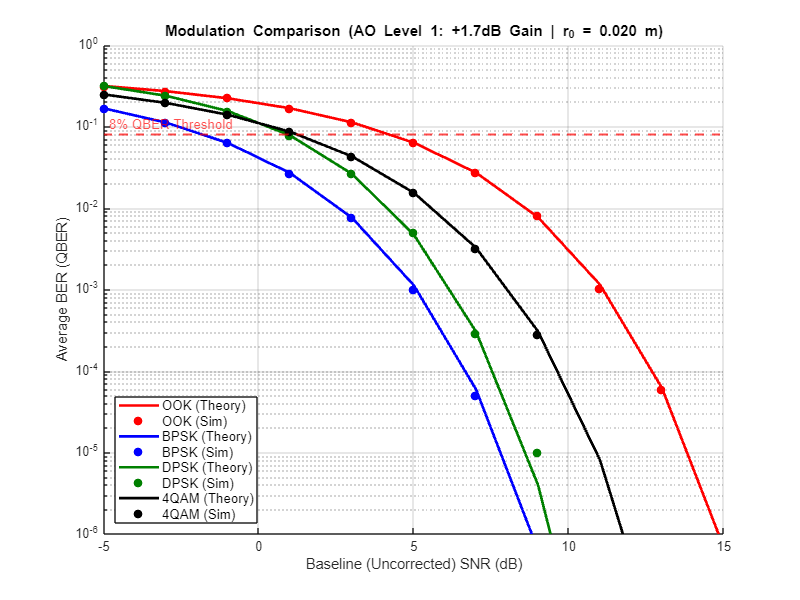

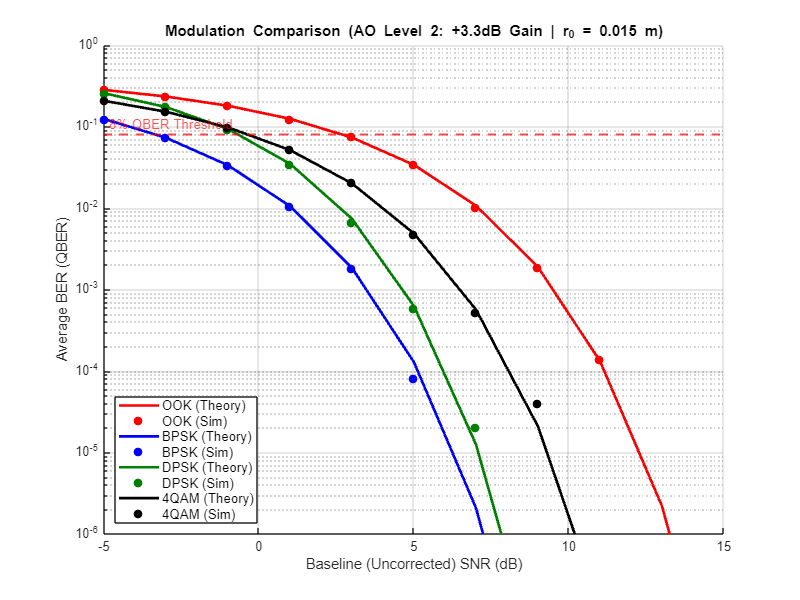

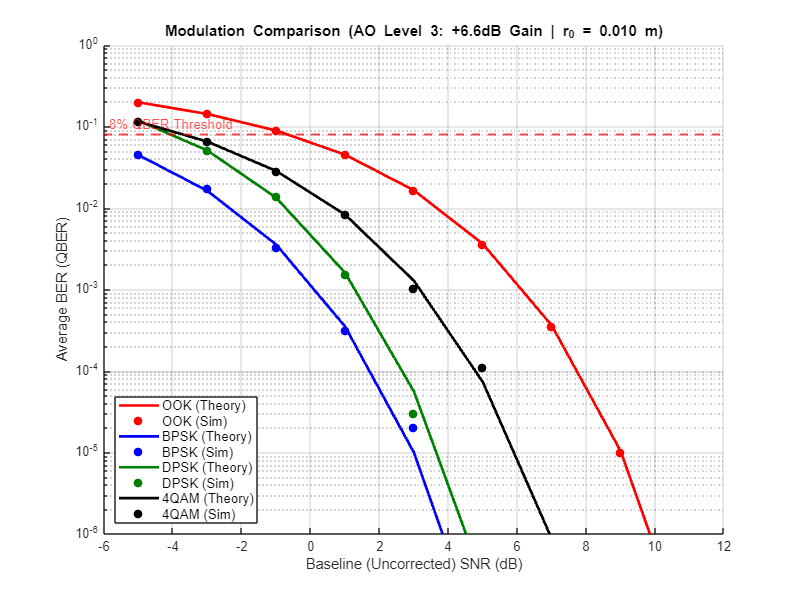


% Using the same RGB triplets for consistency
color_map = containers.Map({'OOK', 'BPSK', 'DPSK', 'QAM4'}, ...
    {[1, 0, 0], [0, 0, 1], [0, 0.5, 0], [0, 0, 0]}); 

% QKD Security Threshold
qber_threshold = 0.08; 

% Loop through 4 states: 0 = Uncorrected, 1 = Level 1, 2 = Level 2, 3 = Level 3
for ao_state = 0:3
    figure('Position', [150 + ao_state*50, 150 + ao_state*50, 800, 600]); 
    hold on;
    
    for s = 1:length(schemes_to_run)
        mod_scheme = schemes_to_run{s};
        c = color_map(mod_scheme); 
        display_name = strrep(mod_scheme, 'QAM4', '4QAM');
        
        if ao_state == 0
            % --- UNCORRECTED BASELINE ---
            data = results.(mod_scheme).level_1;
            mask = ~data.is_zero_E;
            
            % Plot Theory & Sim
            semilogy(data.snr_E, data.theory_E, '-', 'Color', c, 'LineWidth', 2, 'DisplayName', sprintf('%s (Theory)', display_name));
            semilogy(data.snr_E(mask), data.ber_E(mask), 'o', 'Color', c, 'MarkerFaceColor', c, 'MarkerSize', 6, 'DisplayName', sprintf('%s (Sim)', display_name));
            
            % Title dynamically uses the r0_value selected above
            title_str = sprintf('Modulation Comparison (Uncorrected Channel | r_0 = %.3f m)', r0_values(ao_state+1));
        else
            % --- AO CORRECTED LEVELS ---
            level_name = sprintf('level_%d', ao_state);
            data = results.(mod_scheme).(level_name);
            mask = ~data.is_zero_D;
            
            % Plot Theory & Sim
            semilogy(data.snr_E, data.theory_D, '-', 'Color', c, 'LineWidth', 2, 'DisplayName', sprintf('%s (Theory)', display_name));
            semilogy(data.snr_E(mask), data.ber_D(mask), 'o', 'Color', c, 'MarkerFaceColor', c, 'MarkerSize', 6, 'DisplayName', sprintf('%s (Sim)', display_name));
            
            % Title dynamically uses Gain and the r0_value selected above
            title_str = sprintf('Modulation Comparison (AO Level %d: +%.1fdB Gain | r_0 = %.3f m)', ao_state, data.gain_dB, r0_values(ao_state+1));
        end
    end
    
    % Add the QBER Security Threshold Line
    yline(qber_threshold, '--r', '8% QBER Threshold', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left', 'HandleVisibility', 'off');
    
    hold off;
    
    % Formatting
    xlabel('Baseline (Uncorrected) SNR (dB)'); 
    ylabel('Average BER (QBER)');
    title(title_str);
    grid on;
    set(gca, 'YScale', 'log', 'YLim', [1e-6 1]);
    
    legend('Location', 'southwest', 'FontSize', 10);
end

%% 7. AO Efficiency Analysis (SNR Threshold for k Improvement)

% Define your targets
target_k = 2.5;         % Target improvement factor (Uncorrected BER / Corrected BER)
target_ao_level = 1;    % Choose which AO level to evaluate (1 = Low, 2 = Mid, 3 = High)

level_name = sprintf('level_%d', target_ao_level);

fprintf('\n--- AO Efficiency Analysis (Target k = %.1f) ---\n', target_k);


--- AO Efficiency Analysis (Target k = 2.5) ---


fprintf('Evaluating %s...\n\n', level_name);

Evaluating level_1...




for s = 1:length(schemes_to_run)
    mod_scheme = schemes_to_run{s};
    display_name = strrep(mod_scheme, 'QAM4', '4QAM');
    
    % Extract the theoretical data for this specific modulation and AO level
    data = results.(mod_scheme).(level_name);
    
    % Calculate the ratio K at every existing SNR point
    % K = Uncorrected BER / Corrected BER
    K_array = data.theory_E ./ data.theory_D;
    snr_array = data.snr_E;
    
    % Generate a high-resolution SNR grid (10,000 points) for precise threshold detection
    fine_snr = linspace(min(snr_array), max(snr_array), 10000);
    
    % Interpolate the K ratio across the fine grid using 'pchip' (shape-preserving)
    fine_K = interp1(snr_array, K_array, fine_snr, 'pchip');
    
    % Find the index of the first point where the K ratio hits or exceeds our target
    idx_threshold = find(fine_K >= target_k, 1);
    
    % Output the results
    if ~isempty(idx_threshold)
        snr_threshold = fine_snr(idx_threshold);
        fprintf('%s:\n', display_name);
        fprintf('  -> SNR Threshold: %5.2f dB \n', snr_threshold);
        fprintf('  -> Meaning: For any SNR > %.2f dB, AO makes BER at least %.1fx smaller.\n\n', snr_threshold, target_k);
    else
        fprintf('%s:\n', display_name);
        fprintf('  -> Target improvement of %.1fx never reached in this simulated SNR range.\n\n', target_k);
    end
end

OOK:


  -> SNR Threshold:  8.10 dB 


  -> Meaning: For any SNR > 8.10 dB, AO makes BER at least 2.5x smaller.



BPSK:


  -> SNR Threshold:  2.08 dB 


  -> Meaning: For any SNR > 2.08 dB, AO makes BER at least 2.5x smaller.



DPSK:


  -> SNR Threshold:  2.83 dB 


  -> Meaning: For any SNR > 2.83 dB, AO makes BER at least 2.5x smaller.



4QAM:


  -> SNR Threshold:  5.10 dB 


  -> Meaning: For any SNR > 5.10 dB, AO makes BER at least 2.5x smaller.



fprintf('--------------------------------------------------\n');

--------------------------------------------------


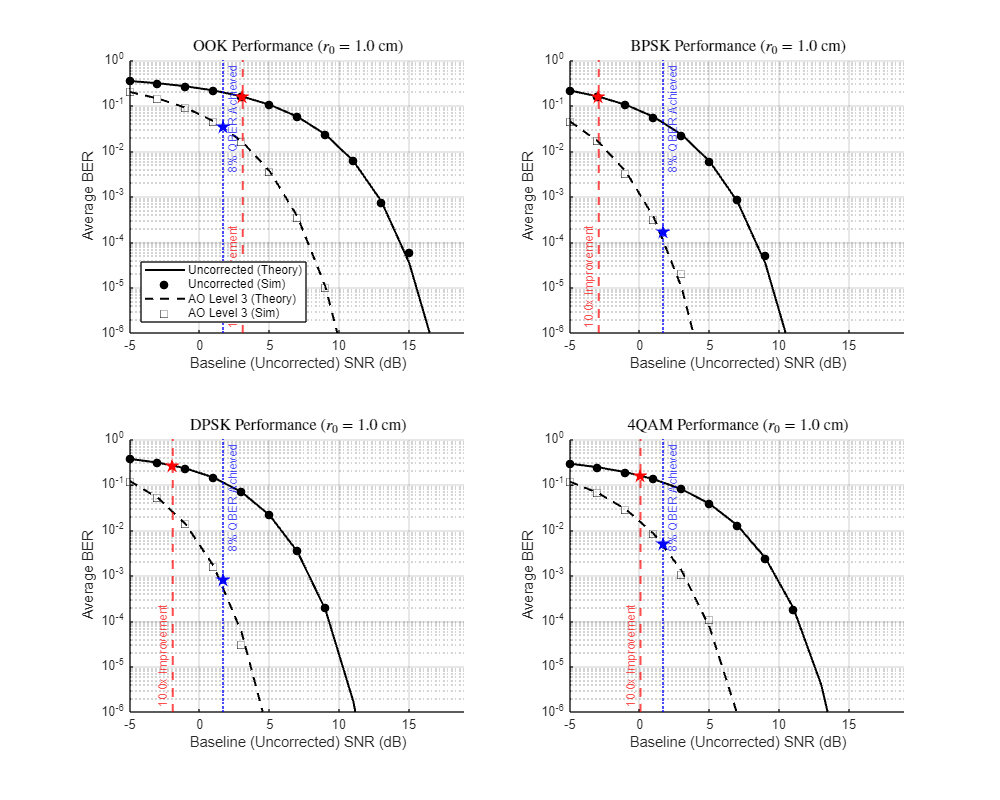

%% 8. AO Efficiency & Security Threshold Visualization (2x2 Grid)

% --- PREDETERMINED VALUES ---
target_k = 10;         % Target improvement factor (Uncorrected BER / Corrected BER)
target_ao_level = 3;   % Which AO level to evaluate (1 = Low, 2 = Mid, 3 = High)
qber_threshold = 0.08; % 8% QBER Security limit
% ----------------------------

level_name = sprintf('level_%d', target_ao_level);

% Create a new full-screen-ish figure for the 2x2 grid
figure('Position', [100, 100, 1000, 800], 'Name', sprintf('AO Efficiency & Security Analysis'));

for s = 1:length(schemes_to_run)
    mod_scheme = schemes_to_run{s};
    display_name = strrep(mod_scheme, 'QAM4', '4QAM');
    
    subplot(2, 2, s);
    hold on;
    
    data = results.(mod_scheme).(level_name);
    
   % --- 1. CALCULATE THE THRESHOLDS ---
    fine_snr = linspace(min(data.snr_E), max(data.snr_E), 10000);
    
    % A. Calculate K-Factor threshold (Classical Improvement)
    K_array = data.theory_E ./ data.theory_D;
    fine_K = interp1(data.snr_E, K_array, fine_snr, 'pchip');
    idx_k_threshold = find(fine_K >= target_k, 1);
    
    % B. Calculate TRUE QBER Security threshold (Quantum Security)
    % We use the quantum formula to find the secure SNR, NOT the classical BER
    e_opt = 0.015; % Baseline optical error (adjust if yours is different)
    effective_snr_linear = 10.^((fine_snr + data.gain_dB) / 10);
    fine_true_QBER = e_opt + (0.5 ./ (effective_snr_linear + 1));
    idx_qber_threshold = find(fine_true_QBER <= qber_threshold, 1);
    
    % --- 2. PLOT THE DATA ---
    % Uncorrected Data
    mask_E = ~data.is_zero_E;
    p1 = semilogy(data.snr_E, data.theory_E, '-k', 'LineWidth', 1.5, 'DisplayName', 'Uncorrected (Theory)');
    p2 = semilogy(data.snr_E(mask_E), data.ber_E(mask_E), 'ok', 'MarkerFaceColor', 'k', 'MarkerSize', 6, 'DisplayName', 'Uncorrected (Sim)');
    
    % Corrected Data
    mask_D = ~data.is_zero_D;
    p3 = semilogy(data.snr_E, data.theory_D, '--k', 'LineWidth', 1.5, 'DisplayName', sprintf('AO Level %d (Theory)', target_ao_level));
    p4 = semilogy(data.snr_E(mask_D), data.ber_D(mask_D), 'sk', 'MarkerSize', 7, 'DisplayName', sprintf('AO Level %d (Sim)', target_ao_level));
    
    % --- 3. PLOT THE THRESHOLD LINES ---
    title_suffix = '';
    
    % Plot K-Factor Line (Red Dashed)
    if ~isempty(idx_k_threshold)
        snr_k = fine_snr(idx_k_threshold);
        xline(snr_k, '--r', sprintf('%.1fx Improvement', target_k), ...
            'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom', ...
            'LabelHorizontalAlignment', 'left', 'HandleVisibility', 'off', 'FontSize', 9);
        
        % Star marker on the uncorrected curve
        k_ber_marker = interp1(data.snr_E, data.theory_E, snr_k, 'pchip');
        plot(snr_k, k_ber_marker, 'pr', 'MarkerFaceColor', 'r', 'MarkerSize', 10, 'HandleVisibility', 'off');
    else
        title_suffix = [title_suffix, ' | k Not Reached'];
    end
    
    % Plot QBER Security Line (Blue Dotted)
    if ~isempty(idx_qber_threshold)
        snr_qber = fine_snr(idx_qber_threshold);
        xline(snr_qber, ':b', '8% QBER Achieved', ...
            'LineWidth', 1.5, 'LabelVerticalAlignment', 'top', ...
            'LabelHorizontalAlignment', 'right', 'HandleVisibility', 'off', 'FontSize', 9);
        
        % Star marker exactly at the 8% crossing on the corrected curve
        plot(snr_qber, interp1(data.snr_E, data.theory_D, snr_qber, 'pchip'), 'pb', 'MarkerFaceColor', 'b', 'MarkerSize', 10, 'HandleVisibility', 'off');
    else
        title_suffix = [title_suffix, ' | QBER Not Reached'];
    end
    
    % --- 4. FORMATTING ---
    hold off;
    grid on;
    set(gca, 'YScale', 'log', 'YLim', [1e-6 1], 'XLim', [min(data.snr_E) max(data.snr_E)]);
    
    xlabel('Baseline (Uncorrected) SNR (dB)');
    ylabel('Average BER');
    title(sprintf('%s Performance%s', display_name, title_suffix));
    % Extract or define the r0 value (Assuming it is in meters in your code, e.g., 0.045)
    % If it is not in your data struct, simply hardcode it for the level: current_r0 = 0.045;
    if isfield(data, 'r0')
        current_r0_cm = data.r0 * 100; % Convert meters to cm
    else
        current_r0_cm = 1; % Replace with your actual r0 for this specific AO level
    end
    
    % Create the dynamic title
    title(sprintf('%s Performance ($r_0 = %.1f$ cm)', display_name, current_r0_cm), 'Interpreter', 'latex', 'FontSize', 12);
    if s == 1
        legend([p1, p2, p3, p4], 'Location', 'southwest', 'FontSize', 9);
    end
end

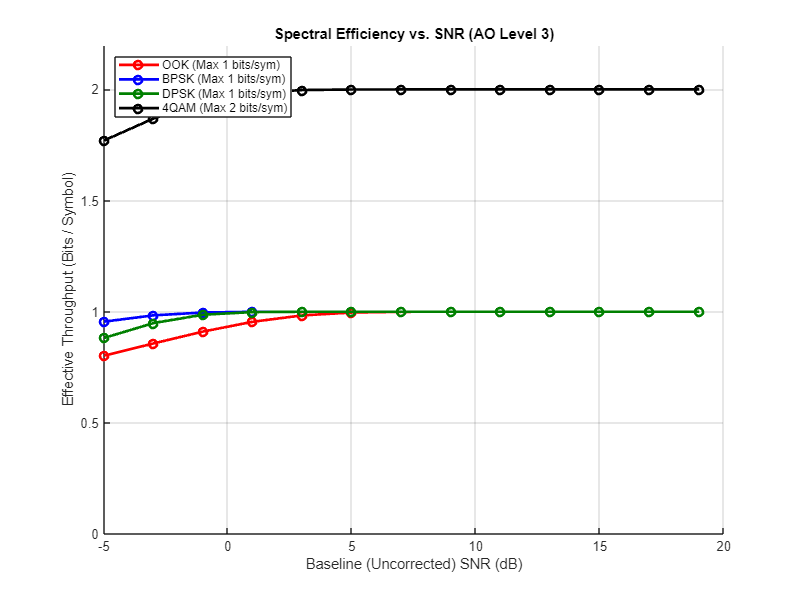

%% 9. Effective Throughput (Goodput) Analysis

figure('Position', [150, 150, 800, 600], 'Name', 'Throughput Trade-off');
hold on;

% Define bits per symbol for each scheme
bits_per_sym = containers.Map({'OOK', 'BPSK', 'DPSK', 'QAM4'}, [1, 1, 1, 2]);
target_ao_level = 3; % Choose which AO level to plot
level_name = sprintf('level_%d', target_ao_level);

for s = 1:length(schemes_to_run)
    mod_scheme = schemes_to_run{s};
    c = color_map(mod_scheme);
    display_name = strrep(mod_scheme, 'QAM4', '4QAM');
    
    data = results.(mod_scheme).(level_name);
    bps = bits_per_sym(mod_scheme);
    
    % Calculate Effective Throughput (Bits per symbol successfully received)
    % Using theoretical BER for smooth curves
    throughput_theory = bps .* (1 - data.theory_D); 
    
    plot(data.snr_E, throughput_theory, '-o', 'Color', c, 'LineWidth', 2, ...
        'DisplayName', sprintf('%s (Max %d bits/sym)', display_name, bps));
end

hold off;
grid on;
xlabel('Baseline (Uncorrected) SNR (dB)');
ylabel('Effective Throughput (Bits / Symbol)');
title(sprintf('Spectral Efficiency vs. SNR (AO Level %d)', target_ao_level));
legend('Location', 'northwest');
set(gca, 'YLim', [0 2.2]);

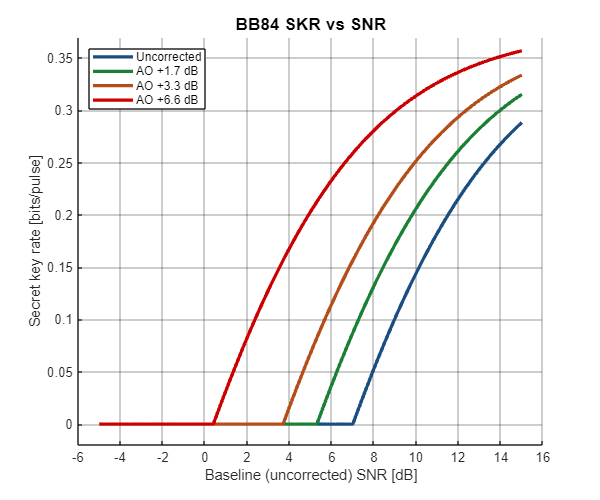

%% 10. BB84 Secret Key Rate (SKR) vs SNR Plot

% 1. Define Parameters
snr_dB_sweep = -5:0.1:15; 
ao_gains = [0, 1.7, 3.3, 6.6]; % The shifts from your image
labels = {'Uncorrected', 'AO +1.7 dB', 'AO +3.3 dB', 'AO +6.6 dB'};
colors = {[0.1, 0.3, 0.5], [0.1, 0.5, 0.2], [0.7, 0.3, 0.1], [0.8, 0, 0]};

f_EC = 1.16;       % Error correction inefficiency (from your paper)
e_opt = 0.015;     % Baseline optical error (approx 1.5%)
qber_threshold = 0.11; % 11% security threshold

% Binary Entropy Function
h = @(x) -(x .* log2(x + eps) + (1 - x) .* log2(1 - x + eps));

figure('Position', [200, 200, 600, 500], 'Name', 'BB84 SKR vs SNR');
hold on;

for i = 1:length(ao_gains)
    current_gain = ao_gains(i);
    
    % Shift the SNR by the AO gain
    effective_snr_dB = snr_dB_sweep + current_gain;
    effective_snr_linear = 10.^(effective_snr_dB / 10);
    
    % Model QBER as a function of SNR
    % Q = (e_opt * Signal + DarkCounts) / (Signal + 2*DarkCounts)
    % Simplified here as an inverse relation to SNR with an e_opt floor
    Q = e_opt + (0.5 ./ (effective_snr_linear + 1));
    
    % Cap QBER at 0.5 (completely random)
    Q(Q > 0.5) = 0.5;
    
    % Calculate Secret Key Rate (SKR)
    % SKR = 0.5 * max(0, 1 - f_EC * h(Q) - h(Q))
    SKR = 0.5 .* (1 - f_EC .* h(Q) - h(Q));
    
    % Set any negative SKR values to 0 (Security threshold crossed)
    SKR(SKR < 0) = 0;
    
    % Plot
    plot(snr_dB_sweep, SKR, 'Color', colors{i}, 'LineWidth', 2.5, 'DisplayName', labels{i});
end

hold off;
grid on;
% Match the visual styling of the reference image
set(gca, 'GridAlpha', 0.3, 'MinorGridAlpha', 0.1); 

xlabel('Baseline (uncorrected) SNR [dB]', 'FontSize', 11);
ylabel('Secret key rate [bits/pulse]', 'FontSize', 11);
title('BB84 SKR vs SNR', 'FontSize', 13);
legend('Location', 'northwest', 'FontSize', 9);
xlim([-6 16]);
ylim([-0.02 0.37]);

%% 11. The Adaptive Modulation "Intersection" Plot (For Discussion Section)

target_ao_level = 1; % Using Level 3 as the representative case
level_name = sprintf('level_%d', target_ao_level);

% --- DYNAMIC r0 LOOKUP ---
target_idx = target_intervals(target_ao_level); 
current_r0 = mean_r0(target_idx);
if current_r0 < 1
    current_r0_cm = current_r0 * 100;
else
    current_r0_cm = current_r0;
end
% -------------------------

classical_safe_ber = 1e-3; 
qber_threshold = 0.08;     
e_opt = 0.015;

figure('Position', [250, 250, 800, 500], 'Name', 'Adaptive Strategy');
hold on;

% 1. Find the Quantum Security SNR (Where the system "Turns On")
data_bpsk = results.BPSK.(level_name);
fine_snr = linspace(min(data_bpsk.snr_E), max(data_bpsk.snr_E), 10000);
effective_snr_linear = 10.^((fine_snr + data_bpsk.gain_dB) / 10);
fine_true_QBER = e_opt + (0.5 ./ (effective_snr_linear + 1));
idx_qber = find(fine_true_QBER <= qber_threshold, 1);
secure_snr = fine_snr(idx_qber);

% 2. Find where 4-QAM becomes Classically Safe
data_4qam = results.QAM4.(level_name);
fine_4qam_ber = interp1(data_4qam.snr_E, data_4qam.theory_D, fine_snr, 'pchip');
idx_4qam_safe = find(fine_4qam_ber <= classical_safe_ber, 1);
safe_4qam_snr = fine_snr(idx_4qam_safe);

% 3. Plot the "Reliable" Throughput
% If BER > safe_ber, throughput = NaN (it drops off the graph)
bpsk_theory = data_bpsk.theory_D;
qam_theory = data_4qam.theory_D;

bpsk_throughput = 1 .* (1 - bpsk_theory);
qam_throughput = 2 .* (1 - qam_theory);

bpsk_throughput(bpsk_theory > classical_safe_ber) = NaN;
qam_throughput(qam_theory > classical_safe_ber) = NaN;

plot(data_bpsk.snr_E, bpsk_throughput, '-ob', 'LineWidth', 2, 'MarkerFaceColor', 'b', 'DisplayName', 'BPSK (Anchor Mode)');
plot(data_4qam.snr_E, qam_throughput, '-sk', 'LineWidth', 2, 'MarkerFaceColor', 'k', 'DisplayName', '4-QAM (Accelerator Mode)');

% 4. Add the Vertical Thresholds
xline(secure_snr, '--b', 'Quantum Security Achieved', 'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom');
xline(safe_4qam_snr, '--k', '4-QAM Becomes Reliable', 'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'left');
% --- NEW: Calculate the Uncorrected Security Threshold ---
% Evaluate the quantum formula WITHOUT adding the AO gain
effective_snr_linear_uncorrected = 10.^(fine_snr / 10);
fine_true_QBER_uncorrected = e_opt + (0.5 ./ (effective_snr_linear_uncorrected + 1));
idx_qber_uncorr = find(fine_true_QBER_uncorrected <= qber_threshold, 1);

if ~isempty(idx_qber_uncorr)
    secure_snr_uncorr = fine_snr(idx_qber_uncorr);
    
    % Draw the Uncorrected Threshold (Red Line)
    xline(secure_snr_uncorr, '-.r', 'Uncorrected Security Threshold', ...
        'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom', ...
        'LabelHorizontalAlignment', 'right', 'HandleVisibility', 'off');
    
    % Draw the AO Shift Arrow
    % Places an arrow at Y = 1.5 pointing from the Uncorrected line to the Corrected line
    arrow_y = 1.5; 
    plot([secure_snr_uncorr, secure_snr], [arrow_y, arrow_y], '-k', 'LineWidth', 2, 'HandleVisibility', 'off');
    plot(secure_snr, arrow_y, '<k', 'MarkerFaceColor', 'k', 'MarkerSize', 10, 'HandleVisibility', 'off');
    
    % Add Text above the arrow
    text(mean([secure_snr_uncorr, secure_snr]), arrow_y + 0.05, ...
        sprintf('AO Gain Shift (+%.1f dB)', data_bpsk.gain_dB), ...
        'HorizontalAlignment', 'center', 'FontSize', 24, 'FontWeight', 'bold');
end

% 5. Shade the background zones
y_lims = [0 2.2];
% Zone 1: Insecure (Red)
fill([min(data_bpsk.snr_E) secure_snr secure_snr min(data_bpsk.snr_E)], [y_lims(1) y_lims(1) y_lims(2) y_lims(2)], 'r', 'FaceAlpha', 0.05, 'EdgeColor', 'none', 'HandleVisibility', 'off');
% Zone 2: BPSK Only (Yellow)
fill([secure_snr safe_4qam_snr safe_4qam_snr secure_snr], [y_lims(1) y_lims(1) y_lims(2) y_lims(2)], 'y', 'FaceAlpha', 0.05, 'EdgeColor', 'none', 'HandleVisibility', 'off');
% Zone 3: 4-QAM Active (Green)
fill([safe_4qam_snr max(data_bpsk.snr_E) max(data_bpsk.snr_E) safe_4qam_snr], [y_lims(1) y_lims(1) y_lims(2) y_lims(2)], 'g', 'FaceAlpha', 0.05, 'EdgeColor', 'none', 'HandleVisibility', 'off');

hold off;
grid on;
xlabel('Baseline (Uncorrected) SNR (dB)');
ylabel('Reliable Throughput (Bits / Symbol)');
title(sprintf('Adaptive Modulation Strategy: Reliability vs. Throughput ($r_0 = %.1f$ cm)', current_r0_cm), ...
    'Interpreter', 'latex', 'FontSize', 24);
legend('Location', 'northwest');
% --- DYNAMIC X-AXIS LIMITS ---
% Calculate dynamic boundaries based on where the thresholds actually land
x_min = floor(secure_snr) - 2; % Add 2 dB of padding to the left of the blue line

% Find the furthest right line (either the red uncorrected line or the black 4QAM line)
if exist('secure_snr_uncorr', 'var') && ~isempty(secure_snr_uncorr)
    furthest_right = max(secure_snr_uncorr, safe_4qam_snr);
else
    furthest_right = safe_4qam_snr;
end

x_max = ceil(furthest_right) + 2; % Add 2 dB of padding to the right

% Apply the dynamic limits
set(gca, 'YLim', y_lims, 'XLim', [x_min, x_max]);
% --- FORMATTING FOR IEEE PUBLICATION ---
% 1. Enlarge the axes tick numbers
set(gca, 'FontSize', 24); 

% 2. Enlarge and bold the axis labels
xlabel('Baseline (Uncorrected) SNR (dB)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Reliable Throughput (Bits / Symbol)', 'FontSize', 14, 'FontWeight', 'bold');

% 3. Enlarge the title (Consider dropping the subtitle to save space)
title(sprintf('Adaptive Modulation Strategy ($r_0 = %.1f$ cm)', current_r0_cm), ...
    'Interpreter', 'latex', 'FontSize', 24, 'FontWeight', 'bold');

% 4. Enlarge the legend
lgd = legend('Location', 'northwest');
lgd.FontSize = 12;

%% 6. Save Data to a Designated Path
% NOTE: Make sure to change this string to an actual folder on your PC!
save_path = 'C:\Users\yizha\OneDrive\Desktop\'; 
if ~exist(save_path, 'dir')
    mkdir(save_path);
end
file_name = fullfile(save_path, 'modulation_results.mat');
save(file_name, 'results');
fprintf('\nResults successfully saved to: %s\n', file_name);


Results successfully saved to: C:\Users\yizha\OneDrive\Desktop\modulation_results.mat
